load("AllSolvedData10000.mat", 'AllSolvedData')
head(AllSolvedData)

          Var1              Var2     
    ________________    _____________

    1×1 occupancyMap    {37×3 double}
    1×1 occupancyMap    {21×3 double}
    1×1 occupancyMap    {24×3 double}
    1×1 occupancyMap    {39×3 double}
    1×1 occupancyMap    {21×3 double}
    1×1 occupancyMap    {49×3 double}
    1×1 occupancyMap    {33×3 double}
    1×1 occupancyMap    {30×3 double}



Database = AllSolvedData;
statespace = stateSpaceSE2;
statespace.StateBounds = [[0 200]; [0 200]; [-3.1416 3.1416]];

mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];

split = 0.8;
trainData = Database(1:800,:);
validationData = Database(801:end,:);

dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);

preparedDataSample = read(dsValidation);
preparedDataSample(1,:)

ans = 1×2 cell array
    {[1.4450 0.7500 1 0.5000 1.4250 1.1800 1 0.5000 0.1782 0.1906 0.1906 0.1906 0.1906 0.1906 0.1906 0.1906 0.1782 0.1906 0.1894 0.4339 0.3766 0.2995 0.3675 0.2677 0.3098 0.1906 0.1906 0.2314 0.2359 0.1633 0.5240 0.5510 0.1270 0.2858 0.1906 0.1906 0.2314 0.2359 0.6125 0.7555 0.5762 0.1951 0.2858 0.1906 0.1139 0.4289 0.4294 0.7356 1 0.6629 0.5898 0.5898 0.1906 0.0206 0.3494 0.3584 0.5427 0.8984 0.4492 0.1407 0.1407 0.1906 0.1906 0.2722 0.1665 0.5036 0.8984 0.4492 0 0.1044 0.1906 0.1906 0.3403 0.4855 0.6398 0.6398 0.4638 0.2858 0.2858 0.1906 0.1782 0.1906 0.1906 0.1906 0.1906 0.1906 0.1906 0.1906 0.1782]}    {[1.4243 0.7640 0.9935 0.5802]}


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:04        0.001                            102.31
            1        1       00:00:04        0.001          104.02                  
           50        5       00:00:07        0.001          6.5635                  
          100        9       00:00:10        0.001          2.7278                  
          150       13       00:00:12        0.001          1.7958                  
          200       17       00:00:15        0.001          1.4446                  
          250       21       00:00:18        0.001          1.2644                  
          300       25       00:00:26        0.001          1.0452            1.2011
          350       30       00:00:28        0.001         0.93996                  
          400       34       00:00:31        0.001         0.8778

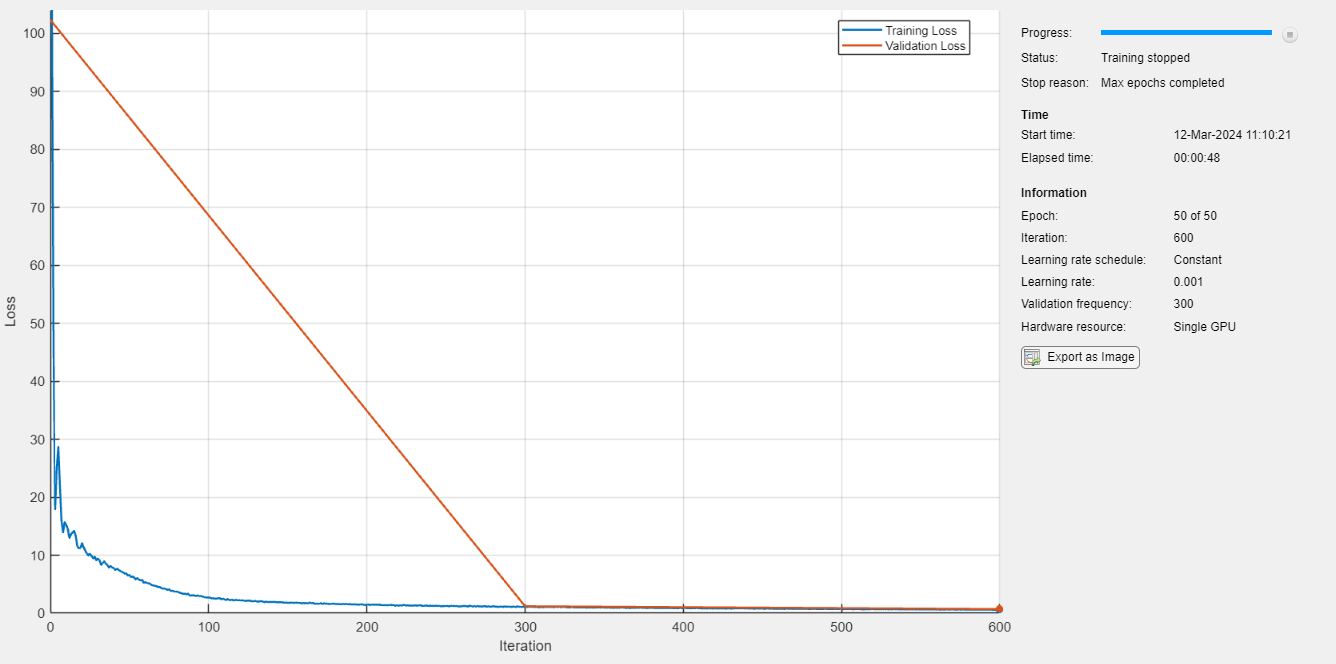

options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=50,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=300,...
        Plots="training-progress");

    % Train network
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);

    
    % Update Network property of mpnet object with net
mpnet.Network = net;



stateSamplerDL = stateSamplerMPNET(statespace,mpnet)

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [100 100 -3.1416]
                GoalState: [100 100 -3.1416]
        MaxLearnedSamples: 50
            GoalThreshold: 1



ind = randi(height(validationData));
map = validationData(ind,:).Var1;
start = double(validationData(ind,:).Var2{1,:}(1,:));
goal = double(validationData(ind,:).Var2{1,:}(end,:));

map(1)

ans =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [200 200]
             XLocalLimits: [0 200]
             YLocalLimits: [0 200]
             XWorldLimits: [0 200]
             YWorldLimits: [0 200]



stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateSamplerDL

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [103 90 0]
                GoalState: [63 160 0]
        MaxLearnedSamples: 50
            GoalThreshold: 1


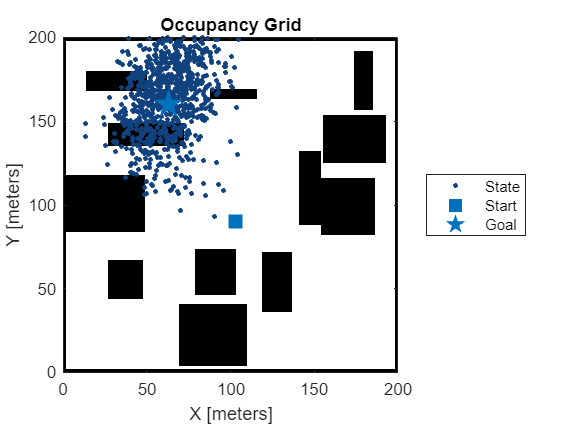

numSamples =1000;
stateSamplerDL.MaxLearnedSamples = 1000;
samples = sample(stateSamplerDL, numSamples);
figure
show(map);
hold on;
plot(samples(:,1),samples(:,2),plannerLineSpec.state{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="eastoutside")

stateValidator = validatorOccupancyMap(statespace,Map=map);
stateValidator.ValidationDistance = 0.1;

start

start =    103    90     0


goal

goal =     63   160     0


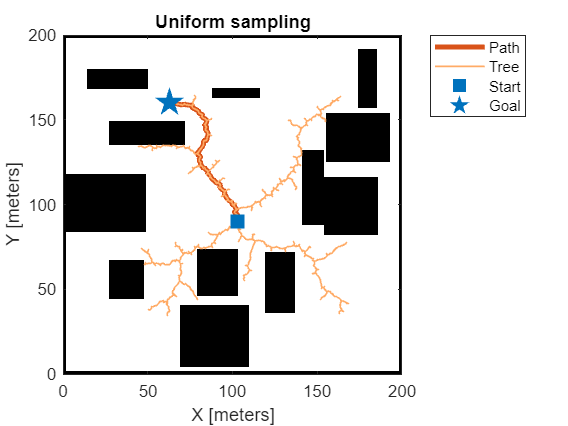


% Create RRT* planner with default uniform sampler
plannerUniformSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerUniform(statespace));
[pathUniformSampling,solutionInfoUniformSampling] = plan(plannerUniformSampling,start,goal);

% Visualize results for uniform sampling
figure
show(map)
hold on;
plot(pathUniformSampling.States(:,1),pathUniformSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoUniformSampling.TreeData(:,1),solutionInfoUniformSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="northeastoutside")
title("Uniform sampling")

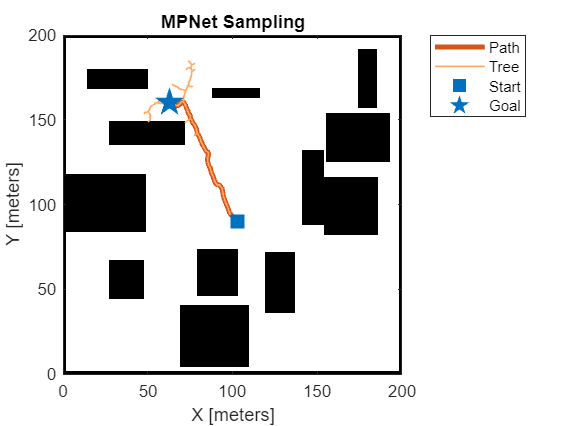

plannerDLSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")

% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=1);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=1,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

Initializing Uniform ...
Done.
Planning a path from the start pose (103 90 0) to the goal pose (63 160 0) using Uniform.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 14.
Executing run 15.
Executing run 16.
Executing run 17.
Executing run 18.
Executing run 19.
Executing run 20.
Executing run 21.
Executing run 22.
Executing run 23.
Executing run 24.
Executing run 25.
Executing run 26.
Executing run 27.
Executing run 28.
Executing run 29.
Executing run 30.
Initializing MPNet ...
Done.
Planning a path from the start pose (103 90 0) to the goal pose (63 160 0) using MPNet.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Execut

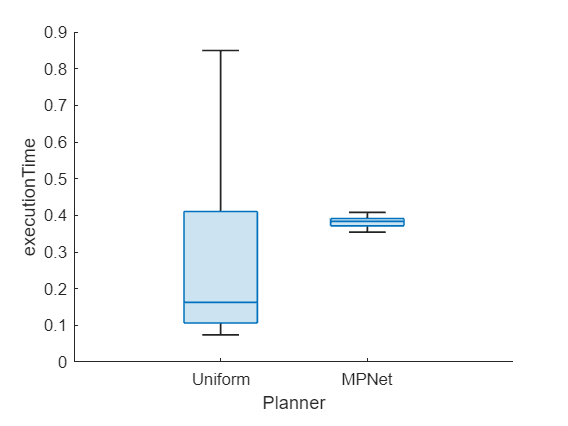

figure
show(pb,"executionTime")

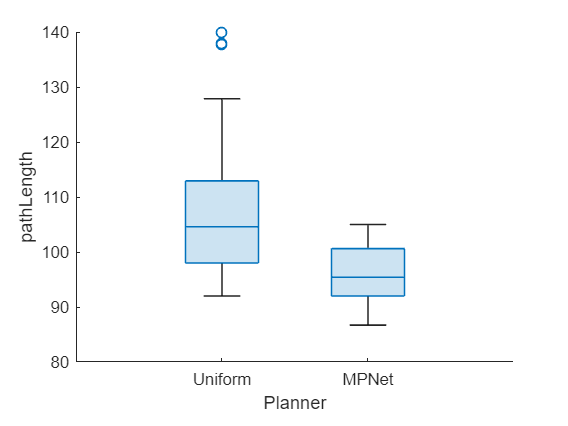

figure
show(pb,"pathLength")

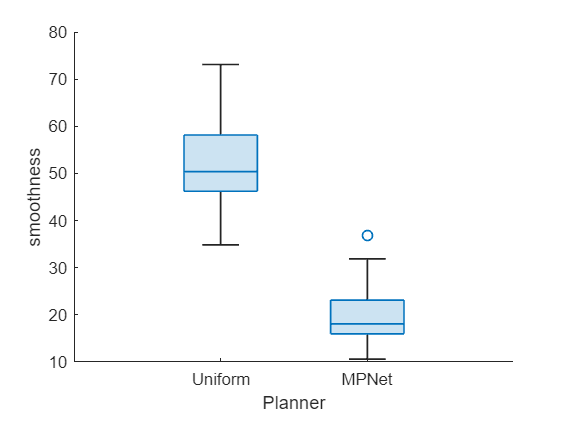

figure
show(pb,"smoothness")